# Compact test signal measurement

## Read test signal and measured signal

[xTest,fs] = audioread("compactTestSig48k.wav");
%[xMes,fsMes] = audioread("compactTestSig48kIKiLMML.wav"); % cal signal 73.0 dB
%[xMes,fsMes] = audioread("hotelRecTest.wav");
%[xMes,fsMes] = audioread("macBookPro.wav");
%[xMes,fsMes] = audioread("compactTestiPhoneFix2.wav"); % cal signal 78.3.0 dB
%xMes(1:71843+300) = xMes(1:71843+300)/1000;
%[xMes,fsMes] = audioread("compactTestiPhoneFix3.wav"); % cal signal 78.3.0 dB
testFileName = "boseIkomaTest48kBi.wav";% cal signal 78.0 dB at 32cm
%testFileName = "boseIkomaTest48kOmni.wav";
%testFileName = "iLoudMMikm48kBi.wav";% cal signal 80.0dB at 32cm
%testFileName = "iLoudMMikm48kOmni.wav";% cal signal 80.0dB at 32cm
%testFileName = "iLoudMMikm48kCard.wav";% cal signal 80.0dB at 32cm
%testFileName = "iLoudMMikm48kSSCCard.wav";% cal signal 80.0dB at 32cm SSCreen
%testFileName = "iLoudMMikm48kSSCOmni.wav";% cal signal 80.0dB at 32cm SSCreen
%testFileName = "iLoudMMikm48kSSCBi.wav";% cal signal 80.0dB at 32cm SSCreen
[xMes,fsMes] = audioread(testFileName); % 

xCal1s = xTest(16*fs+(1:fs));
xCal60s = zeros(fs*60,1);
for ii = 1:60
   xCal60s((ii-1)*fs+(1:fs)) = xCal1s; 
end
%audiowrite("oneOctSS48kHz60s.wav",xCal60s,fs,"BitsPerSample",24);

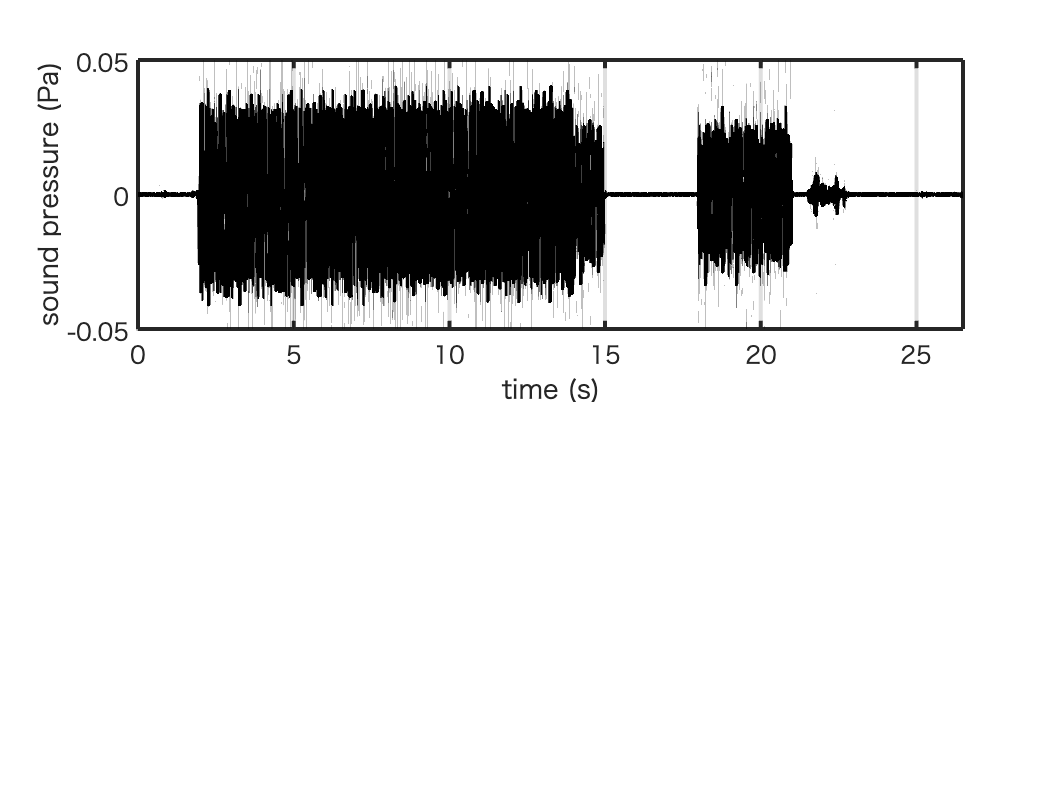

cfCal = 78-20*log10(std(xCal1s));
xPa = xMes*10^(cfCal/20)*20*10^(-6);
figure;
tiledlayout(2,1);
nexttile
plot((1:length(xMes))'/fs,xPa,"k","LineWidth",2);
grid on
axis([ 0 length(xMes)/fs -0.05 0.05])
set(gca,"linewidth",2,"fontsize",12)
xlabel("time (s)")
ylabel("sound pressure (Pa)")

tmp = char(testFileName);
segCheckFile = tmp(1:end-4)+"SPL.jpg";
%print("-djpeg","-r200",segCheckFile)


## Detect reference Position2

xPwr = abs(xMes).^2;
smoothedxPwr = abs(fftfilt(ones(round(fs*0.001),1),xPwr));
onsetThreshold = max(smoothedxPwr)/10^(16/10); % -25 dB
baseIdx = 1:length(smoothedxPwr);
onSet = min(baseIdx(smoothedxPwr>onsetThreshold))

onSet = 95035

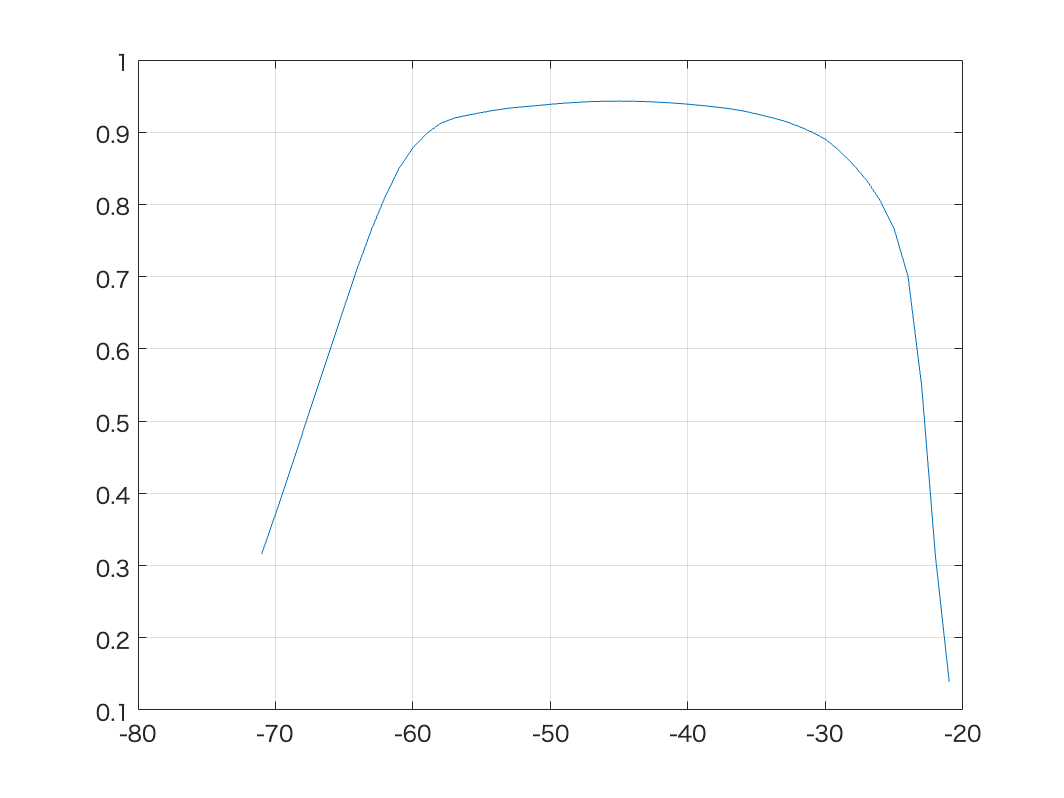

sortedPwr = sort(smoothedxPwr);
sortedPwrRev = sort(smoothedxPwr,"descend");
nBin = length(sortedPwr);
lvlLow = 10*log10(sortedPwr(round(0.1*nBin)));
lvlHi = 10*log10(sortedPwrRev(round(0.1*nBin)));
thCandidate = round(lvlLow):round(lvlHi);
sigma2 = zeros(length(thCandidate),1);
smoothePwrDb = 10*log10(smoothedxPwr);
for ii = 1:length(thCandidate)
    w0 = sum(smoothePwrDb<thCandidate(ii))/nBin;
    w1 = sum(smoothePwrDb>=thCandidate(ii))/nBin;
    sigm0 = std(smoothePwrDb(smoothePwrDb<thCandidate(ii)))^2;
    sigm1 = std(smoothePwrDb(smoothePwrDb>=thCandidate(ii)))^2;
    sigma2(ii) = w0*sigm0+w1*sigm1;
end
figure;
plot(thCandidate,(std(smoothePwrDb)^2-sigma2)/std(smoothePwrDb)^2);grid on;

[~,bestTh] = min(sigma2);
onsetThreshold = 10^(thCandidate(bestTh)/10);
baseIdx = 1:length(smoothedxPwr);
onSet = min(baseIdx(smoothedxPwr>onsetThreshold))

onSet = 95031

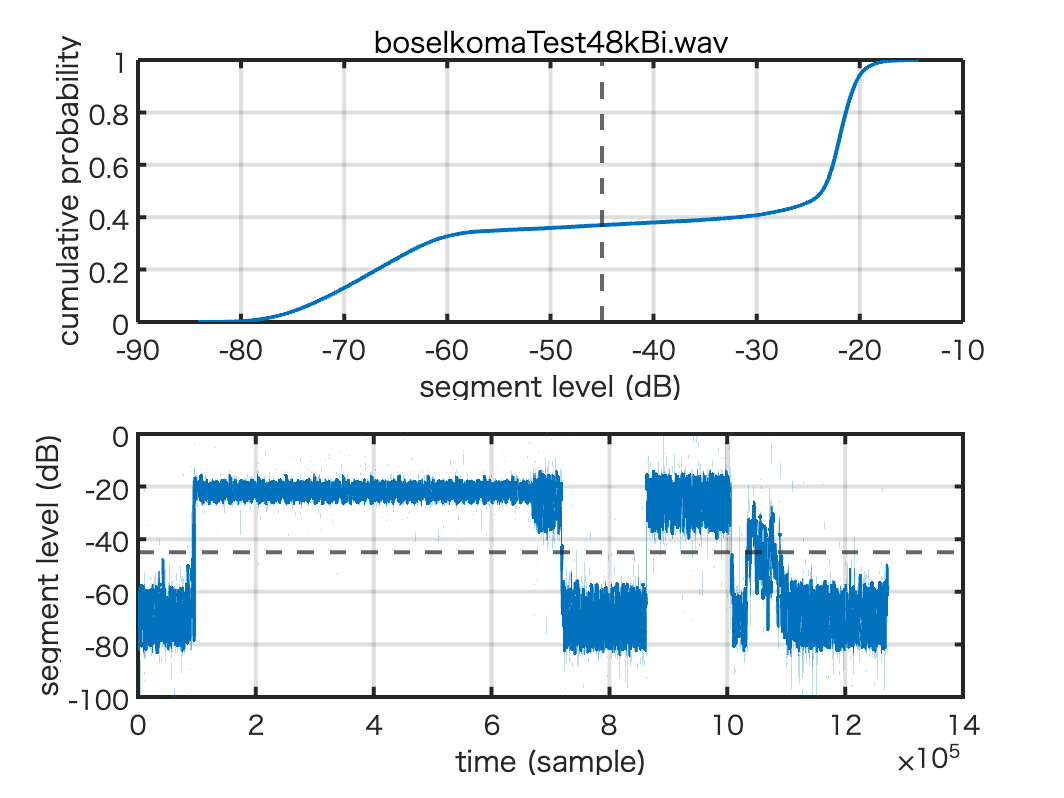


figure;
tiledlayout(2,1);
nexttile
plot(sort(10*log10(smoothedxPwr)),...
    (1:length(smoothedxPwr))/length(smoothedxPwr),"LineWidth",2);grid on;
xline(10*log10(onsetThreshold),"--","LineWidth",2)
set(gca,"linewidth",2,"fontsize",13)
ylabel("cumulative probability")
xlabel("segment level (dB)")
title(testFileName)
nexttile;
plot(10*log10(smoothedxPwr),"LineWidth",2);grid on;
yline(10*log10(onsetThreshold),"--","LineWidth",2)
set(gca,"linewidth",2,"fontsize",13)
ylabel("segment level (dB)")
xlabel("time (sample)")
tmp = char(testFileName);
segCheckFile = tmp(1:end-4)+"SegMenting.jpg";
print("-djpeg","-r200",segCheckFile)

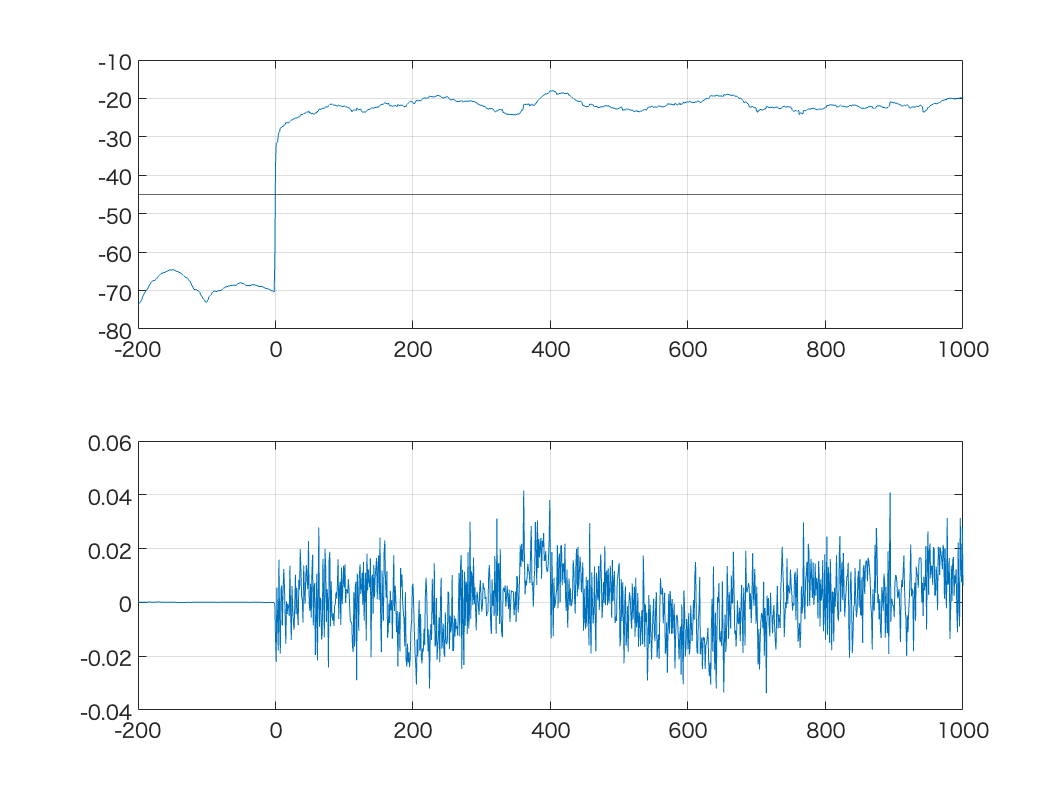


figure;
tiledlayout(2,1);
nexttile
plot(-200:1000,10*log10(smoothedxPwr(onSet+(-200:1000))));grid on;
yline(10*log10(onsetThreshold))
nexttile
plot(-200:1000,xMes(onSet+(-200:1000)));grid on;


xRef = xTest(fs+(1:fs));
xMp1 = xMes(fs*2+onSet-200+(1:fs));
xMm1 = xMes(fs*8+onSet-200+(1:fs));
fx = (0:fs-1)'/fs*fs;
fxBi = fx;
fxBi(fx>fs/2) = fxBi(fx>fs/2)-fs;
idxSel = abs(fxBi)>40;
iRespP1 = real(ifft(fft(xMp1)./fft(xRef).*idxSel));
iRespM1 = -real(ifft(fft(xMm1)./fft(xRef).*idxSel));
fff = (30000:48000);
20*log10(mean(abs(iRespM1(fff))))

ans = -95.9814

20*log10(mean(abs(iRespM1(fff)+iRespP1(fff))/2))

ans = -112.8318

20*log10(mean(abs(iRespM1(fff)-iRespP1(fff))/2))

ans = -96.0573

pBias = round((-0.5:0.1:4.9)*fs);
nBias = length(pBias);
stdDbPos = zeros(nBias,1);
stdDbNeg = zeros(nBias,1);
stdDbAve = zeros(nBias,1);
stdDbDiff = zeros(nBias,1);
for jj = 1:nBias
    xRef = xTest(fs+(1:fs)+pBias(jj));
    xMp1 = xMes(fs+onSet-200+(1:fs)+pBias(jj));
    xMm1 = xMes(round(fs*6)+onSet-200+(1:fs)+pBias(jj));
    iRespP1 = real(ifft(fft(xMp1)./fft(xRef).*idxSel));
    iRespM1 = -real(ifft(fft(xMm1)./fft(xRef).*idxSel));
    stdDbPos(jj) = 20*log10(mean(abs(iRespP1(fff))));
    stdDbNeg(jj) = 20*log10(mean(abs(iRespM1(fff))));
    stdDbAve(jj) = 20*log10(mean(abs(iRespM1(fff)+iRespP1(fff))/2));
    stdDbDiff(jj) = 20*log10(mean(abs(iRespM1(fff)-iRespP1(fff))/2));
end

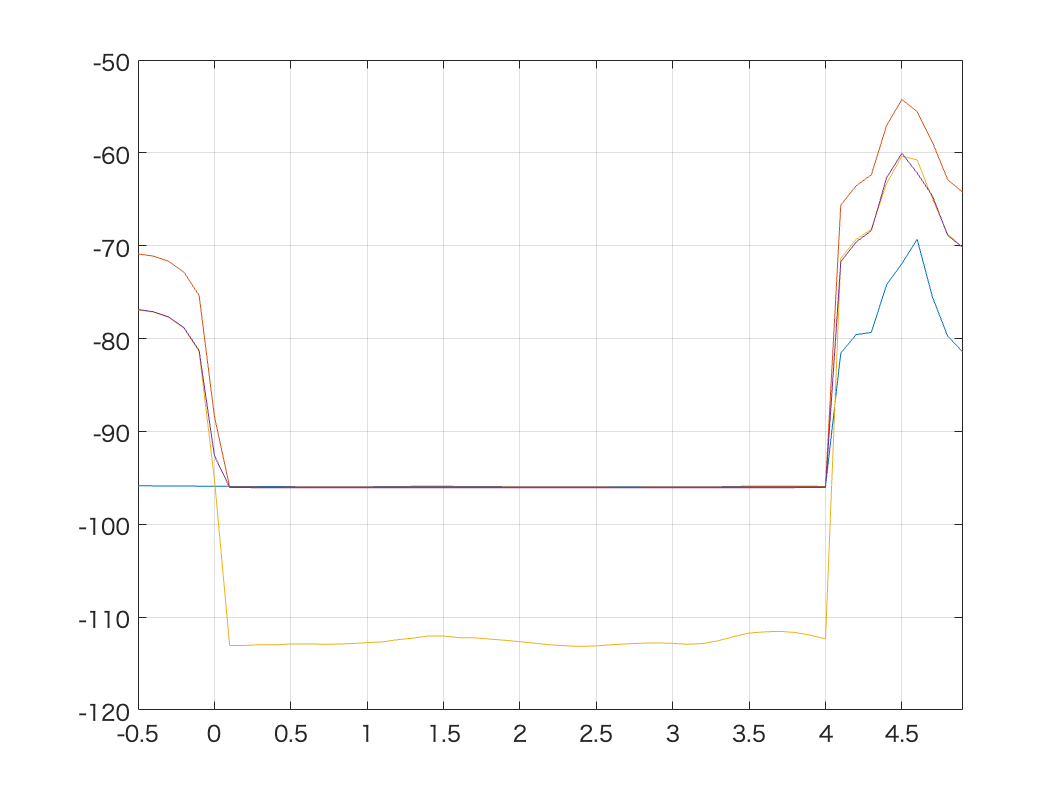

figure;plot(pBias/fs, stdDbPos);grid on;
hold all;plot(pBias/fs, stdDbNeg);grid on;
hold all;plot(pBias/fs, stdDbAve);grid on;
hold all;plot(pBias/fs, stdDbDiff);grid on;
set(gca,"xlim",pBias([1 end])/fs)

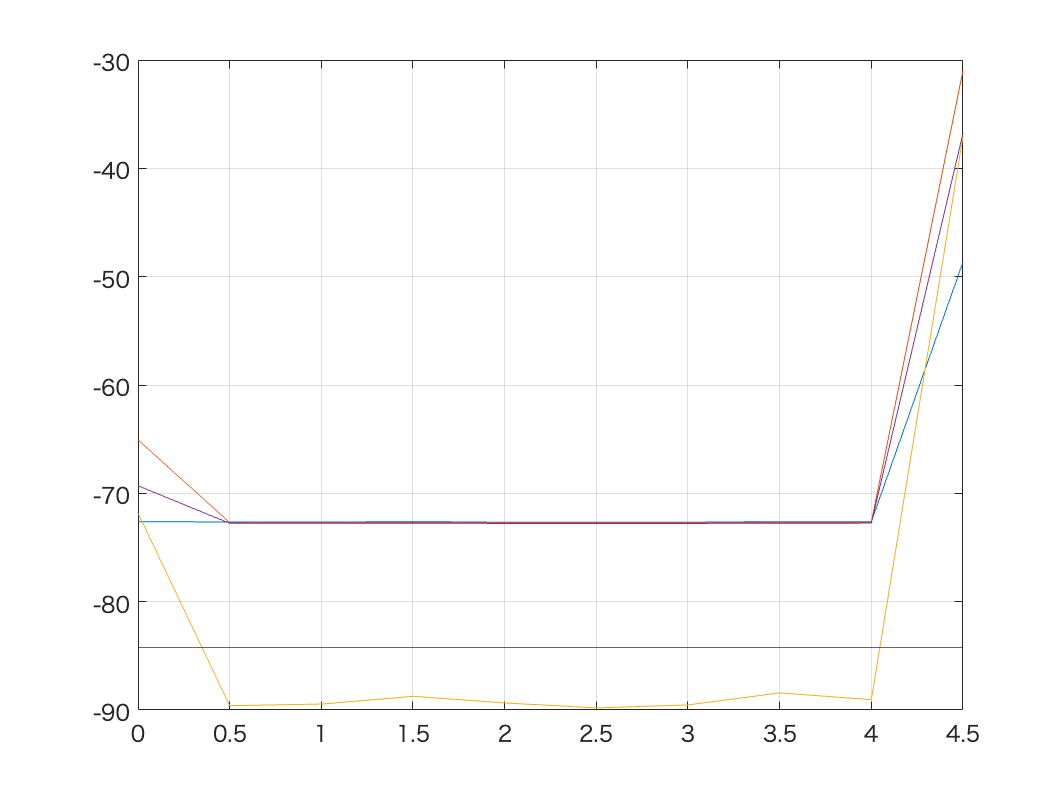

pBias = round((0:0.5:4.9)*fs);
nBias = length(pBias);
stdDbPos = zeros(nBias,1);
stdDbNeg = zeros(nBias,1);
stdDbAve = zeros(nBias,1);
stdDbDiff = zeros(nBias,1);
iRespP1Mat = zeros(fs,nBias);
iRespM1Mat = zeros(fs,nBias);
jj = 1;
stdRatio = std(xTest(fs+(1:fs)+pBias(jj)))/std(xMes(fs*1+onSet-200+(1:fs)+pBias(jj)));
for jj = 1:nBias
    xRef = xTest(fs+(1:fs)+pBias(jj));
    xMp1 = xMes(fs*1+onSet-200+(1:fs)+pBias(jj));
    xMm1 = xMes(fs*6+onSet-200+(1:fs)+pBias(jj));
    iRespP1 = real(ifft(fft(xMp1)./fft(xRef).*idxSel))*stdRatio;
    iRespM1 = -real(ifft(fft(xMm1)./fft(xRef).*idxSel))*stdRatio;
    stdDbPos(jj) = 20*log10(mean(abs(iRespP1(fff))));
    stdDbNeg(jj) = 20*log10(mean(abs(iRespM1(fff))));
    stdDbAve(jj) = 20*log10(mean(abs(iRespM1(fff)+iRespP1(fff))/2));
    stdDbDiff(jj) = 20*log10(mean(abs(iRespM1(fff)-iRespP1(fff))/2));
    iRespP1Mat(:,jj) = iRespP1;
    iRespM1Mat(:,jj) = iRespM1;
end
figure;plot(pBias/fs, stdDbPos);grid on;
hold all;plot(pBias/fs, stdDbNeg);grid on;
hold all;plot(pBias/fs, stdDbAve);grid on;
hold all;plot(pBias/fs, stdDbDiff);grid on;
reliableLevel = median(stdDbAve)+5;
yline(reliableLevel);

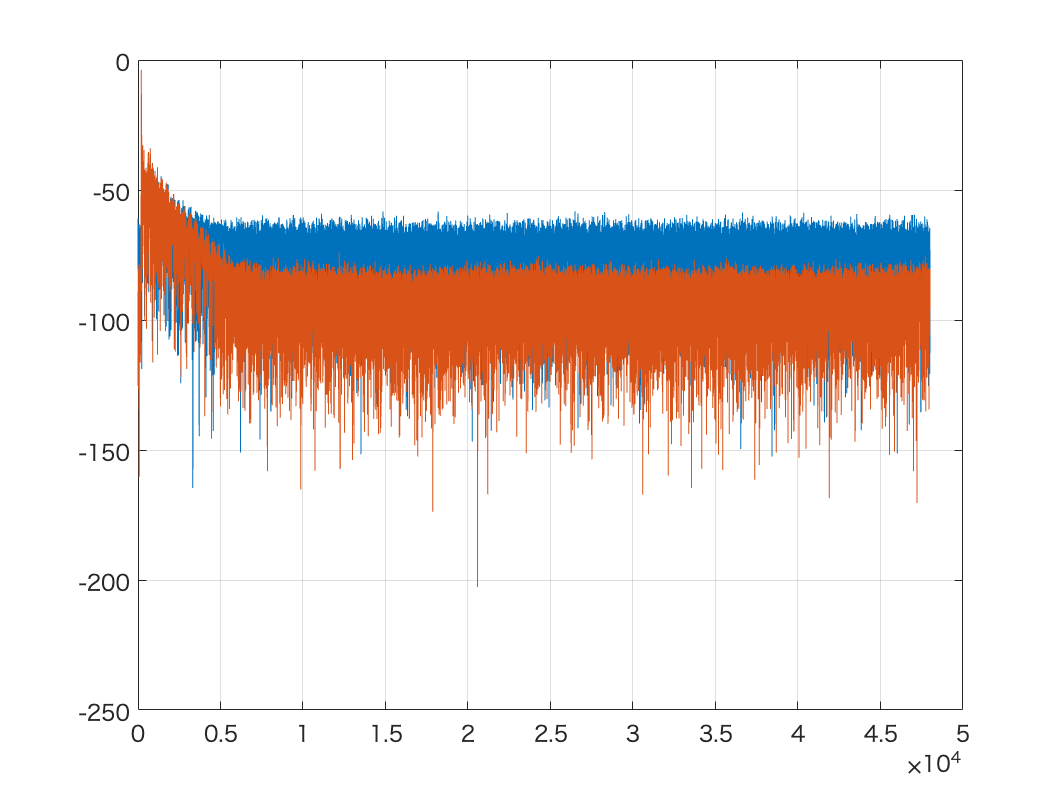


idxSet = 1:nBias;
reliableSet = idxSet(stdDbAve< reliableLevel);
reliableSetOn = min(reliableSet);
reliableSetOff = max(reliableSet);%-1;
reliableSet = idxSet(idxSet>=reliableSetOn & idxSet <= reliableSetOff);

iRespP1Ave = mean(iRespP1Mat(:,reliableSet),2);
iRespM1Ave = mean(iRespM1Mat(:,reliableSet),2);

figure;plot(20*log10(abs(iRespP1Ave)));grid on;
hold all;plot(20*log10(abs(iRespP1Ave+iRespM1Ave)/2));grid on;

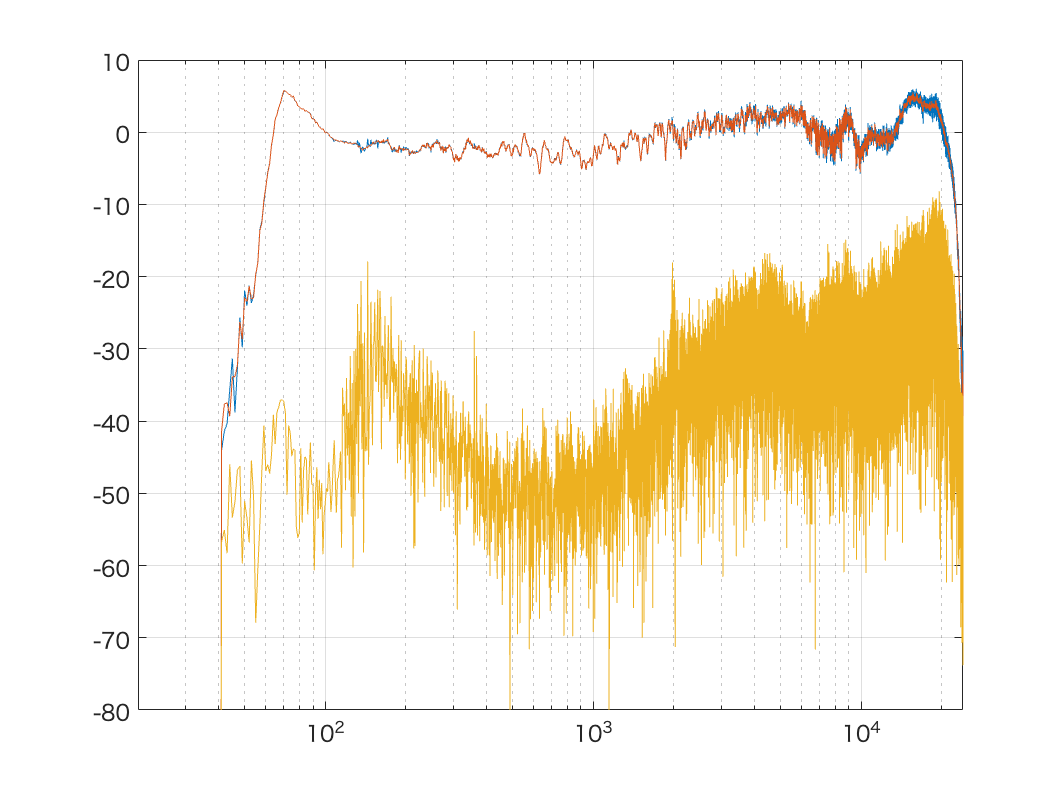

%hold all;plot(20*log10(abs(iRespP1Ave-iRespM1Ave)/2));grid on;

figure;
semilogx(fx,20*log10(abs(fft(iRespP1Mat(:,reliableSetOff)))));grid on;
hold all;semilogx(fx,20*log10(abs(fft(iRespP1Ave+iRespM1Ave)/2)));grid on;
hold all;semilogx(fx,20*log10(abs(fft(iRespP1Ave-iRespM1Ave)/2)));grid on;
axis([20 fs/2 -80 10]);

stdDiff = zeros(fs,1);
%iRespP1Ave2 = 0*mean(iRespP1Mat(:,stdDbPos<-60),2);
%iRespM1Ave2 = 0*mean(iRespM1Mat(:,stdDbPos<-60),2);
nSum = 0;
for ii = 1:nBias-2
    if ismember(ii,reliableSet) && ismember(ii+2,reliableSet)
        nSum = nSum+1;
        stdDiff = stdDiff + abs(fft(iRespP1Mat(:,ii+2)-iRespP1Mat(:,ii))).^2 ...
            + abs(fft(iRespP1Mat(:,ii+2)-iRespP1Mat(:,ii))).^2;
    end
end
stdDiff = stdDiff/nSum/2/2;
%nSum2 = 0;
%for ii = 1:nBias
%    if ismember(ii,reliableSet) 
%        nSum2 = nSum2+1;
%        iRespP1Ave2 = iRespP1Ave2 + iRespP1Mat(:,ii);
%        iRespM1Ave2 = iRespM1Ave2 + iRespM1Mat(:,ii);
%    end
%end
%iRespP1Ave2 = iRespP1Ave2/nSum2;
%iRespM1Ave2 = iRespM1Ave2/nSum2;
ttb = (1:fs)'/fs-200/fs;2

ans = 2

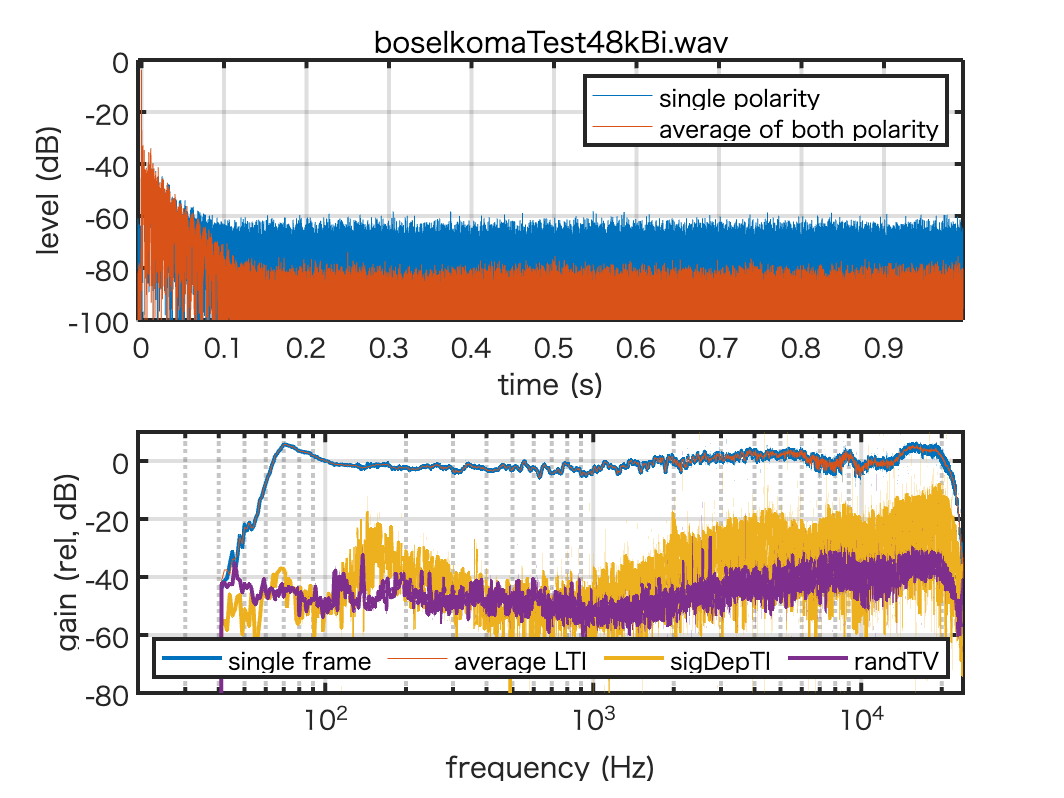


figure;
tiledlayout(2,1)
nexttile
plot(ttb,20*log10(abs(iRespP1Ave)));grid on;
hold all;plot(ttb,20*log10(abs(iRespP1Ave+iRespM1Ave)/2));grid on;
axis([ttb(1) ttb(end) -100 0])
set(gca,"linewidth",2,"fontsize",13)
xlabel("time (s)")
ylabel("level (dB)")
legend("single polarity","average of both polarity")
title(testFileName)

%figure;
nexttile
semilogx(fx,20*log10(abs(fft(iRespP1Mat(:,reliableSetOff)))),"LineWidth",2);grid on;
hold all;semilogx(fx,20*log10(abs(fft(iRespP1Ave+iRespM1Ave)/2)));grid on;
hold all;semilogx(fx,20*log10(abs(fft(iRespP1Ave-iRespM1Ave)/2)),"LineWidth",2);grid on;
hold all;semilogx(fx,10*log10(stdDiff),"LineWidth",2);grid on;
axis([20 fs/2 -80 10]);
set(gca,"linewidth",2,"fontsize",13)
xlabel("frequency (Hz)")
ylabel("gain (rel, dB)")
legend("single frame","average LTI","sigDepTI","randTV","location","south","Orientation","horizontal")

tmp = char(testFileName);
outFileName = tmp(1:end-4)+"multiAttrMes.eps";
%print("-depsc",outFileName)
%print -depsc AKGiLoudTest.eps